mouse='1610';
timepoint='c';


for i=1:4
    eval(['lft_',mouse,'_',timepoint,'_',num2str(i),'=median_',num2str(i),';'])
    eval(['intensity_',mouse,'_',timepoint,'_',num2str(i),'=median_',num2str(i),'_intensity;'])
end

The epoch based median was collected using the code above and saved in 'medians_sleep.mat'. Now I can start with loading this matlab data file.

load('/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/medians_sleep.mat')

mouse_all=["1610","1611","1612","1626","1627","1629","1630"]

mouse_all = 1×7 string array
    "1610"    "1611"    "1612"    "1626"    "1627"    "1629"    "1630"


timepoints=["a","b","c"]

timepoints = 1×3 string array
    "a"    "b"    "c"



for i=1:7
    mouse=convertStringsToChars(mouse_all(i))
    eval(['mouse',mouse,'_lft=[];'])
    eval(['mouse',mouse,'_intensity=[];'])
    eval(['mouse',mouse,'_states=[];'])
    for j=1:4
        eval(['mouse',mouse,'_lft_',num2str(j),'=[lft_',mouse,'_a_',num2str(j),' lft_',mouse,'_b_',num2str(j),' lft_',mouse,'_c_',num2str(j),'];'])
        eval(['mouse',mouse,'_intensity_',num2str(j),'=[intensity_',mouse,'_a_',num2str(j),' intensity_',mouse,'_b_',num2str(j),' intensity_',mouse,'_c_',num2str(j),'];'])
        eval(['mouse',mouse,'_lft=[mouse',mouse,'_lft mouse',mouse,'_lft_',num2str(j),'];'])
        eval(['mouse',mouse,'_intensity=[mouse',mouse,'_intensity mouse',mouse,'_intensity_',num2str(j),'];'])
        eval(['mouse',mouse,'_state_',num2str(j),'=zeros(1,length(mouse',mouse,'_lft_',num2str(j),'))+j;'])
        eval(['mouse',mouse,'_states=[mouse',mouse,'_states mouse',mouse,'_state_',num2str(j),'];'])
    end
    eval(['mouse',mouse,'_mouseID=zeros(1, length(mouse',mouse,'_states))+i;'])
end

mouse = '1610'

mouse = '1611'

mouse = '1612'

mouse = '1626'

mouse = '1627'

mouse = '1629'

mouse = '1630'



for i=1:7
    mouse=convertStringsToChars(mouse_all(i))
    eval(['mouse',mouse,'_timepoints=[];'])
    for j=1:4
        for k=1:3
            timepoint=convertStringsToChars(timepoints(k));
            eval(['state_x_timepoint=lft_',mouse,'_',timepoint,'_',num2str(j),';'])
            eval(['mouse',mouse,'_timepoints=[mouse',mouse,'_timepoints zeros(1,length(state_x_timepoint))+k];'])
        end
    end
end

mouse = '1610'

mouse = '1611'

mouse = '1612'

mouse = '1626'

mouse = '1627'

mouse = '1629'

mouse = '1630'

all_lft=[];
all_intensity=[];
all_states=[];
all_mouseID=[];
all_timepoints=[];
for i=1:7
    mouse=convertStringsToChars(mouse_all(i))
    eval(['all_lft=[all_lft mouse',mouse,'_lft];'])
    eval(['all_intensity=[all_intensity mouse',mouse,'_intensity];'])
    eval(['all_states=[all_states mouse',mouse,'_states];'])
    eval(['all_mouseID=[all_mouseID mouse',mouse,'_mouseID];'])
    eval(['all_timepoints=[all_timepoints mouse',mouse,'_timepoints];'])
end

mouse = '1610'

mouse = '1611'

mouse = '1612'

mouse = '1626'

mouse = '1627'

mouse = '1629'

mouse = '1630'


ignored_index = find(all_lft > 4.5);
all_lft(ignored_index) = [];
all_intensity(ignored_index)=[];
all_states(ignored_index)=[];
all_mouseID(ignored_index)=[];
all_timepoints(ignored_index)=[];

NREM_index = find(all_states == 2);
REM_index = find(all_states == 3);
Sleep_index =[NREM_index REM_index];

all_lft_sleep = all_lft(Sleep_index) ;
all_intensity_sleep = all_intensity(Sleep_index);
all_states_sleep = all_states(Sleep_index);
all_mouseID_sleep = all_mouseID(Sleep_index);
all_timepoints_sleep = all_timepoints(Sleep_index);




all_states_str=[];
for i=1:length(all_states)
    all_states_str(i)=num2str(all_states(i));
end

all_states_str_sleep=[];
for i=1:length(all_states_sleep)
    all_states_str_sleep(i)=num2str(all_states_sleep(i));
end
% num2str(all_states);
% all_mouseID_str=num2str(all_mouseID);
% all_timepoints_str=num2str(all_timepoints);

all_states_categorical=(categorical(all_states))';
all_mouseID_categorical=categorical(all_mouseID)';
all_timepoints_categorical=categorical(all_timepoints)';

all_states_categorical_sleep=(categorical(all_states_sleep))';
all_mouseID_categorical_sleep=categorical(all_mouseID_sleep)';
all_timepoints_categorical_sleep=categorical(all_timepoints_sleep)';


categories(all_states_categorical)

ans = 4×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'4'}


categories(all_mouseID_categorical)

ans = 7×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}


categories(all_timepoints_categorical)

ans = 3×1 cell array
    {'1'}
    {'2'}
    {'3'}



categories(all_states_categorical_sleep)

ans = 2×1 cell array
    {'2'}
    {'3'}


categories(all_mouseID_categorical_sleep)

ans = 7×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}


categories(all_timepoints_categorical_sleep)

ans = 3×1 cell array
    {'1'}
    {'2'}
    {'3'}


figure
scatter(zeros(1, length(intensity_1610_a_1))+1,lft_1610_a_1)
hold on
scatter(zeros(1, length(intensity_1610_a_2))+2,lft_1610_a_2)
hold on
scatter(zeros(1, length(intensity_1610_a_3))+3,lft_1610_a_3)
hold on
scatter(zeros(1, length(intensity_1610_a_4))+4,lft_1610_a_4)

lft_tbl_sleep=table(all_states_categorical_sleep, all_mouseID_categorical_sleep, all_timepoints_categorical_sleep, all_lft_sleep')

lft_tbl_sleep = 1142×4 table
    all_states_categorical_sleep    all_mouseID_categorical_sleep    all_timepoints_categorical_sleep          Var4      
    ____________________________    _____________________________    ________________________________    ________________

                 2                                1                                 1                    4.15297836952966
                 2                                1                                 1                    4.15344661178867
                 2                                1                                 1                    4.13491577607649
                 2                                1                                 1                    4.14477584826158
                 2                                1                                 1                 

intensity_tbl_sleep=table(all_states_categorical_sleep, all_mouseID_categorical_sleep, all_timepoints_categorical_sleep, all_intensity_sleep')

intensity_tbl_sleep = 1142×4 table
    all_states_categorical_sleep    all_mouseID_categorical_sleep    all_timepoints_categorical_sleep      Var4  
    ____________________________    _____________________________    ________________________________    ________

                 2                                1                                 1                      121045
                 2                                1                                 1                      120826
                 2                                1                                 1                    119393.5
                 2                                1                                 1                      122673
                 2                                1                                 1                    118502.5
                 2            

mdl3=stepwiseglm(lft_tbl_sleep,'constant','Criterion','adjrsquared')

1. Adding all_states_categorical_sleep, AdjRsquared = 0.49977
2. Adding all_mouseID_categorical_sleep, AdjRsquared = 0.74422
3. Adding all_timepoints_categorical_sleep, AdjRsquared = 0.77691
4. Adding all_mouseID_categorical_sleep:all_timepoints_categorical_sleep, AdjRsquared = 0.86219
5. Adding all_states_categorical_sleep:all_mouseID_categorical_sleep, AdjRsquared = 0.8678


mdl3 = Generalized linear regression model:
    Var4 ~ 1 + all_states_categorical_sleep*all_mouseID_categorical_sleep + all_mouseID_categorical_sleep*all_timepoints_categorical_sleep
    Distribution = Normal

Estimated Coefficients:
                                                                                Estimate                  SE                   tStat                 pValue       
                                                                          ____________________    ___________________    _________________    ____________________

    (Intercept)                                                                 4.149563907122    0.00245703059729036     1688.85316759921                       0
    all_states_categorical_sleep_3                                          0.0706608399875155    0.003443

mdl4=stepwiseglm(intensity_tbl_sleep,'constant','Criterion','adjrsquared')

1. Adding all_mouseID_categorical_sleep, AdjRsquared = 0.58536
2. Adding all_timepoints_categorical_sleep, AdjRsquared = 0.8139
3. Adding all_mouseID_categorical_sleep:all_timepoints_categorical_sleep, AdjRsquared = 0.97783
4. Adding all_states_categorical_sleep, AdjRsquared = 0.99239
5. Adding all_states_categorical_sleep:all_mouseID_categorical_sleep, AdjRsquared = 0.99592
6. Adding all_states_categorical_sleep:all_timepoints_categorical_sleep, AdjRsquared = 0.99629


mdl4 = Generalized linear regression model:
    Var4 ~ 1 + all_states_categorical_sleep*all_mouseID_categorical_sleep + all_states_categorical_sleep*all_timepoints_categorical_sleep + all_mouseID_categorical_sleep*all_timepoints_categorical_sleep
    Distribution = Normal

Estimated Coefficients:
                                                                              Estimate                SE                 tStat                  pValue        
                                                                          _________________    ________________    __________________    _____________________

    (Intercept)                                                            120518.496575086    974.140583903445      123.717765758368                        0
    all_states_categorical_sleep_3                             

States_csv = 'Sleep_states.csv'

States_csv = 'Sleep_states.csv'

lft_csv =  'Lifetime.csv'

lft_csv = 'Lifetime.csv'

intensity_csv = 'Intensity.csv'

intensity_csv = 'Intensity.csv'


csvwrite(States_csv, all_states_sleep')
csvwrite(lft_csv, all_intensity_sleep')
csvwrite(intensity_csv, all_lft_sleep')

lft_tbl=table(all_states_categorical, all_mouseID_categorical, all_timepoints_categorical, all_lft')

intensity_tbl=table(all_states_categorical, all_mouseID_categorical, all_timepoints_categorical, all_intensity')

mdl1=stepwiseglm(lft_tbl,'constant','Criterion','adjrsquared')

1. Adding all_states_categorical, AdjRsquared = 0.34989
2. Adding all_mouseID_categorical, AdjRsquared = 0.63161
3. Adding all_timepoints_categorical, AdjRsquared = 0.66833
4. Adding all_mouseID_categorical:all_timepoints_categorical, AdjRsquared = 0.75875
5. Adding all_states_categorical:all_mouseID_categorical, AdjRsquared = 0.77622
6. Adding all_states_categorical:all_timepoints_categorical, AdjRsquared = 0.7778


mdl1 = Generalized linear regression model:
    Var4 ~ 1 + all_states_categorical*all_mouseID_categorical + all_states_categorical*all_timepoints_categorical + all_mouseID_categorical*all_timepoints_categorical
    Distribution = Normal

Estimated Coefficients:
                                                                    Estimate                   SE                    tStat                  pValue       
                                                              _____________________    ___________________    ___________________    ____________________

    (Intercept)                                                    4.19858721456249    0.00201448665145981       2084.19708888116                       0
    all_states_categorical_2                                    -0.0486809135103065    0.0026079677494663

mdl2=stepwiseglm(intensity_tbl,'constant','Criterion','adjrsquared')

1. Adding all_mouseID_categorical, AdjRsquared = 0.53121
2. Adding all_timepoints_categorical, AdjRsquared = 0.80028
3. Adding all_mouseID_categorical:all_timepoints_categorical, AdjRsquared = 0.976
4. Adding all_states_categorical, AdjRsquared = 0.99103
5. Adding all_states_categorical:all_mouseID_categorical, AdjRsquared = 0.99331
6. Adding all_states_categorical:all_timepoints_categorical, AdjRsquared = 0.99355


mdl2 = Generalized linear regression model:
    Var4 ~ 1 + all_states_categorical*all_mouseID_categorical + all_states_categorical*all_timepoints_categorical + all_mouseID_categorical*all_timepoints_categorical
    Distribution = Normal

Estimated Coefficients:
                                                                  Estimate                SE                 tStat                  pValue        
                                                              _________________    ________________    __________________    _____________________

    (Intercept)                                                139441.107762697    923.948546752169      150.918693744208                        0
    all_states_categorical_2                                  -20886.5123495008    1196.14990268105     -17.4614505278024     

X=[all_states' all_mouseID' all_timepoints'];
Y1=all_lft';
Y2=all_intensity';
mdl1=glmfit(X,Y1)

mdl1 =     4.1705
   -0.0065
    0.0155
    0.0007


mdl1=fitglm(X,Y1)

mdl1 = Generalized linear regression model:
    y ~ 1 + x1 + x2 + x3
    Distribution = Normal

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)        4.1705     0.019224     216.94             0
    x1             -0.0064614    0.0041579     -1.554       0.12028
    x2               0.015456    0.0025375     6.0911    1.2531e-09
    x3             0.00065144    0.0061196    0.10645       0.91523


3237 observations, 3233 error degrees of freedom
Estimated Dispersion: 0.0836
F-statistic vs. constant model: 13.1, p-value = 1.74e-08

mdl2=glmfit(X,Y2)

mdl2 = 1.0e+04 *

    9.5347
   -0.3765
    1.7539
    6.2625


Y=all_states';
X1=all_lft';
X2=all_intensity';

B1=mnrfit(X1,Y)

B1 =   -27.6632  -26.8901  -30.5457
    6.6502    6.3837    7.0267


B2=mnrfit(X2,Y)

B2 =    -0.0904    0.3529   -1.2039
    0.0000   -0.0000    0.0000


mouse_all=["1610","1611","1612","1626","1627","1629","1630"]

mouse_all = 1×7 string array
    "1610"    "1611"    "1612"    "1626"    "1627"    "1629"    "1630"


mouseID = ["1610",
     "1611",
    "1612",
    "1627",
    "1629",
    "1630",
    "1626",
%     #"1626",
    "1627",
%     #"1627",
    "1610",
    "1612",
%     #"1626",
%     #"1611",
%     #"1612",
    "1629",
    "1629",
    "1630",
    "1630"]

mouseID = 14×1 string array
    "1610"
    "1611"
    "1612"
    "1627"
    "1629"
    "1630"
    "1626"
    "1627"
    "1610"
    "1612"
    "1629"
    "1629"
    "1630"
    "1630"



laser = ["1",
    "1",
    "1",
    "1",
    "1",
    "1",
    "1",
%     #"2",
    "2",
%     #"3",
    "3",
    "2",
%     #"3",
%     #"1",
%     #"3",
    "2",
    "3",
    "2",
    "3"]

laser = 14×1 string array
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "2"
    "3"
    "2"
    "2"
    "3"
    "2"
    "3"


cd('/Users/pingchuanma/Desktop/ChenLab_Data/RvR')



% running as 1, resting as 0
lft_all=[];
intensity_all=[];
animalID_all=[];
laser_all=[];
states_all=[];
speed_all=[];


for i=1:14
    mouse=find(mouse_all==mouseID(i));
    laserpower=str2num(laser(i));

    runningcsvfile=['runningDictsOutput',num2str(i-1),'.csv'];
    runningoutput=csvread(runningcsvfile,1,0);
    running_speed_csvfile=['speedOutput',num2str(i-1),'.csv'];
    running_speed_output=csvread(running_speed_csvfile,1,0);
    running_speed_output(:,1)=[];
    running_speed=[];
    for j=1:size(running_speed_output,1)
        running_speed(j,1)=max(running_speed_output(j,:));
    end
    j
    running_lft=runningoutput(:,8);
    running_intensity=runningoutput(:,2);
    n=length(running_lft)
    lft_all=[lft_all;running_lft];
    intensity_all=[intensity_all;running_intensity];
    animalID_all=[animalID_all;zeros(n,1)+mouse];
    laser_all=[laser_all;zeros(n,1)+laserpower];
    states_all=[states_all;zeros(n,1)+1];
    speed_all=[speed_all;running_speed];



    restingcsvfile=['baselineDictsOutput',num2str(i-1),'.csv'];
    restingoutput=csvread(restingcsvfile,1,0);
    resting_lft=restingoutput(:,8);
    resting_intensity=restingoutput(:,2);
    n=length(resting_lft);
    lft_all=[lft_all;resting_lft];
    intensity_all=[intensity_all;resting_intensity];
    animalID_all=[animalID_all;zeros(n,1)+mouse];
    laser_all=[laser_all;zeros(n,1)+laserpower];
    states_all=[states_all;zeros(n,1)];
    speed_all=[speed_all;zeros(n,1)];

   

    
end

j = 31

n = 31

j = 45

n = 45

j = 12

n = 12

j = 13

n = 13

j = 58

n = 58

j = 43

n = 43

j = 29

n = 29

j = 18

n = 18

j = 6

n = 6

j = 24

n = 24

j = 67

n = 67

j = 35

n = 35

j = 52

n = 52

j = 32

n = 32


intensity_all=intensity_all/100000;




lft1610=lft_all(find(animalID_all==1));
intensity1610=intensity_all(find(animalID_all==1));
speed1610=speed_all(find(animalID_all==1));
laser1610=laser_all(find(animalID_all==1));
states1610=states_all(find(animalID_all==1));

lft1610_1=lft1610(find(laser1610==1));
intensity1610_1=intensity1610(find(laser1610==1));
speed1610_1=speed1610(find(laser1610==1));
states1610_1=states1610(find(laser1610==1));
lft1610_1_running=lft1610_1(find(states1610_1==1));
lft1610_1_resting=lft1610_1(find(states1610_1==0));
intensity1610_1_running=intensity1610_1(find(states1610_1==1));
intensity1610_1_resting=intensity1610_1(find(states1610_1==0));


lft1610_2=lft1610(find(laser1610==3));
intensity1610_2=intensity1610(find(laser1610==3));
speed1610_2=speed1610(find(laser1610==3));
states1610_2=states1610(find(laser1610==3));
lft1610_2_running=lft1610_2(find(states1610_2==1));
lft1610_2_resting=lft1610_2(find(states1610_2==0));
intensity1610_2_running=intensity1610_2(find(states1610_2==1));
intensity1610_2_resting=intensity1610_2(find(states1610_2==0));

figure1=figure;
figure1.Position=[10 10 500 400];

scatter(speed1610_1,lft1610_1,'filled')
hold on
scatter(speed1610_2,lft1610_2,'filled')
hold off
legend('Laser1','Laser2','FontSize',24)
xlabel('Speed (cm/s)')
xlim([-0.5 18])
xticks([0 5 10 15])
ylabel('Lifetime (ns)')
ylim([4.15 4.3])
yticks([4.15 4.2 4.25])
ax=gca

ax =   Axes with properties:

             XLim: [-0.5000 18]
             YLim: [4.1500 4.3000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


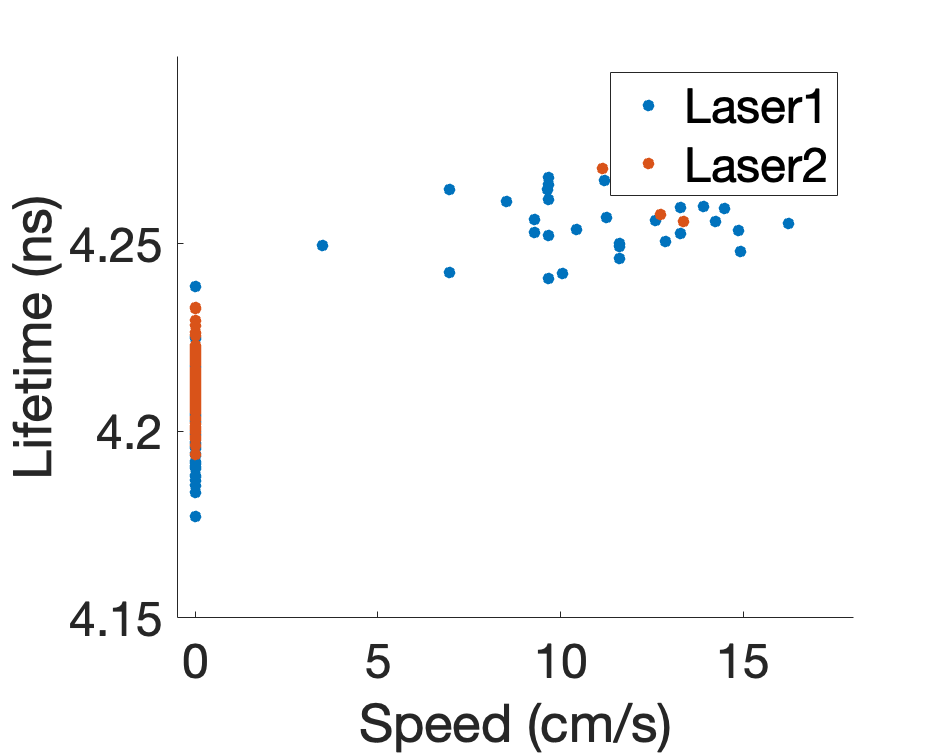

ax =   Axes with properties:

             XLim: [-0.5000 18]
             YLim: [4.1500 4.3000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1766 0.1695 0.7284 0.7555]
            Units: 'normalized'

  Show all properties


ax.FontSize=24


figure2=figure;
figure2.Position=[10 10 500 400];

scatter(speed1610_1,intensity1610_1,'filled')
hold on
scatter(speed1610_2,intensity1610_2,'filled')
hold off
% legend('Laser1','Laser2')
xlabel('Speed (cm/s)')
xlim([-0.5 18])
xticks([0 5 10 15])
ylabel('Intensity')
ylim([250000 450000])
yticks([250000 350000 450000])
ax=gca

ax =   Axes with properties:

             XLim: [-0.5000 18]
             YLim: [250000 450000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


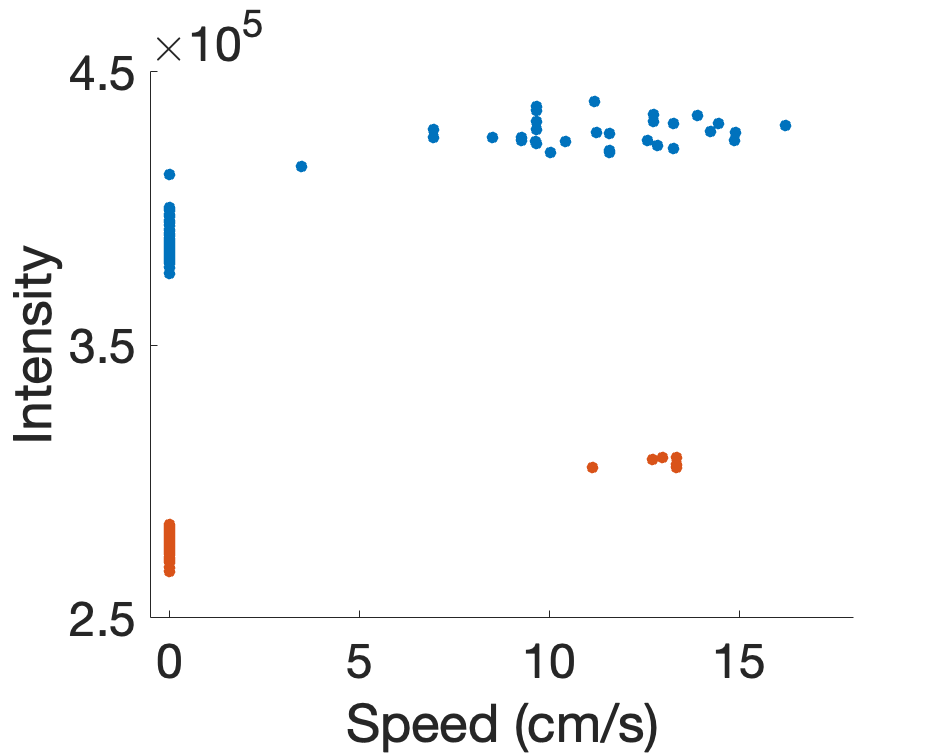

ax =   Axes with properties:

             XLim: [-0.5000 18]
             YLim: [250000 450000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1496 0.1695 0.7554 0.7405]
            Units: 'normalized'

  Show all properties


ax.FontSize=24

% Transform the categorical variables to dummy variables

states_all_categorical=categorical(states_all);
states_all_dv=dummyvar(states_all_categorical);
categories(states_all_categorical)

ans = 2×1 cell array
    {'0'}
    {'1'}



animalID_all_categorical=categorical(animalID_all);
animalID_all_dv=dummyvar(animalID_all_categorical);
categories(animalID_all_categorical)

ans = 7×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}



laser_all_categorical=categorical(laser_all);
laser_all_dv=dummyvar(laser_all_categorical);
categories(laser_all_categorical)

ans = 3×1 cell array
    {'1'}
    {'2'}
    {'3'}


% creat table for glm analysis, use the predictors as categorical
% By default, fitglm takes the last variable as the response variable and the others as the predictor variables
% If data is in a table or dataset array tbl, then, by default, 
% fitglm treats all categorical values, logical values, character arrays, 
% string arrays, and cell arrays of character vectors as categorical variables.

lft_tbl=table(states_all_categorical,animalID_all_categorical,laser_all_categorical,lft_all)
intensity_tbl=table(states_all_categorical,animalID_all_categorical,laser_all_categorical,intensity_all)

mdl1=fitglm(lft_tbl)

mdl1 = Generalized linear regression model:
    lft_all ~ 1 + states_all_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                   Estimate        SE         tStat       pValue  
                                  __________    _________    _______    __________

    (Intercept)                       4.1968    0.0012711     3301.7             0
    states_all_categorical_1        0.054862    0.0009728     56.396             0
    animalID_all_categorical_2     0.0018414    0.0020313    0.90652       0.36483
    animalID_all_categorical_3     0.0090994    0.0016711      5.445    6.1945e-08
    animalID_all_categorical_4    -0.0065388    0.0020099    -3.2533     0.0011701
    

mdl2=fitglm(intensity_tbl)

mdl2 = Generalized linear regression model:
    intensity_all ~ 1 + states_all_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                   Estimate        SE       tStat       pValue   
                                  ___________    ______    _______    ___________

    (Intercept)                    4.1945e+05    3040.8     137.94              0
    states_all_categorical_1            43145    2327.2     18.539     3.2076e-68
    animalID_all_categorical_2    -2.3305e+05    4859.4    -47.959    3.6869e-289
    animalID_all_categorical_3     1.2331e+05    3997.9     30.844    5.3581e-157
    animalID_all_categorical_4    -1.4612e+05    4808.3     -30.39    1.7014e-153
    

% Trying to see whether numbers of these categorical variables matter
% I'm changing the running vs resting from 1 vs 0 to 1 vs 2.
states_all2=states_all;
states_all2(find(states_all2==1))=2;
states_all2_categorical=categorical(states_all2);
categories(states_all2_categorical)

ans = 2×1 cell array
    {'0'}
    {'2'}



lft_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,lft_all)
intensity_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,intensity_all)

mdl3=fitglm(lft_tbl)

mdl3 = Generalized linear regression model:
    lft_all ~ 1 + states_all2_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                   Estimate          SE           tStat       pValue
                                  ___________    __________    ___________    ______

    (Intercept)                        4.2039     0.0008333         5044.9      0   
    states_all2_categorical_2        0.052104    0.00058033         89.784      0   
    animalID_all_categorical_2     1.0429e-14     0.0012944     8.0572e-12      1   
    animalID_all_categorical_3    -1.3548e-14     0.0010961     -1.236e-11      1   
    animalID_all_categorical_4     5.6888e-15     0.0012944      4.395e-12      

mdl4=fitglm(intensity_tbl)

mdl4 = Generalized linear regression model:
    intensity_all ~ 1 + states_all2_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                   Estimate        SE         tStat       pValue
                                  ___________    ______    ___________    ______

    (Intercept)                      3.88e+05     500.4         775.37      0   
    states_all2_categorical_2           39590    348.49          113.6      0   
    animalID_all_categorical_2     3.0249e-10     777.3     3.8916e-13      1   
    animalID_all_categorical_3    -1.5145e-09    658.23    -2.3009e-12      1   
    animalID_all_categorical_4     6.7488e-11     777.3     8.6824e-14      1   
    anima

states_all2=states_all;
states_all2(find(states_all2==0))=2;
states_all2_categorical=categorical(states_all2);
categories(states_all2_categorical)

ans = 2×1 cell array
    {'1'}
    {'2'}



lft_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,lft_all)
intensity_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,intensity_all)

mdl3=fitglm(lft_tbl)

mdl3 = Generalized linear regression model:
    lft_all ~ 1 + states_all2_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                   Estimate          SE           tStat       pValue
                                  ___________    __________    ___________    ______

    (Intercept)                         4.256    0.00090568         4699.2      0   
    states_all2_categorical_2       -0.052104    0.00058033        -89.784      0   
    animalID_all_categorical_2     1.0438e-14     0.0012944     8.0637e-12      1   
    animalID_all_categorical_3    -1.2957e-14     0.0010961    -1.1821e-11      1   
    animalID_all_categorical_4     5.5784e-15     0.0012944     4.3096e-12      

% mdl4=fitglm(intensity_tbl)

states_all3=string(states_all2);

Unrecognized function or variable 'states_all2'.

states_all3(find(states_all3=="1"))="state1";
states_all3(find(states_all3=="2"))="state2";

laser_all3=string(laser_all);
laser_all3(find(laser_all3=="1"))="laser1";
laser_all3(find(laser_all3=="2"))="laser2";
laser_all3(find(laser_all3=="3"))="laser3";

animalID_all3=string(animalID_all);
animalID_all3(find(animalID_all3=="1"))="animal1";
animalID_all3(find(animalID_all3=="2"))="animal2";
animalID_all3(find(animalID_all3=="3"))="animal3";
animalID_all3(find(animalID_all3=="4"))="animal4";
animalID_all3(find(animalID_all3=="5"))="animal5";
animalID_all3(find(animalID_all3=="6"))="animal6";
animalID_all3(find(animalID_all3=="7"))="animal7";


lft_tbl=table(states_all3,animalID_all3,laser_all3,lft_all)
intensity_tbl=table(states_all3,animalID_all3,laser_all3,intensity_all)

mdl3=fitglm(lft_tbl)
mdl4=fitglm(intensity_tbl)


% I'm changing the running vs resting from 1 vs 0 to 6 vs 5.
states_all3=states_all;
states_all3(find(states_all3==0))=5;
states_all3(find(states_all3==1))=6;
states_all3_categorical=categorical(states_all3);
categories(states_all3_categorical)

ans = 2×1 cell array
    {'5'}
    {'6'}



lft_tbl=table(states_all3_categorical,animalID_all_categorical,laser_all_categorical,lft_all)

Unrecognized function or variable 'animalID_all_categorical'.

intensity_tbl=table(states_all3_categorical,animalID_all_categorical,laser_all_categorical,intensity_all)

mdl5=fitglm(lft_tbl)
mdl6=fitglm(intensity_tbl)

% what if I change the numbers to string
states_all_str=strings;
sleep_states=["running" "resting"]

sleep_states = 1×2 string array
    "running"    "resting"


states_all4=states_all;
states_all4(find(states_all==0))=2;

for i=1:length(states_all)
    states_all_str(i,1)=sleep_states(states_all4(i));
end

animalID_all_str=strings;
animalIDs=["animal1" "animal2" "animal3" "animal4" "animal5" "animal6" "animal7"]

animalIDs = 1×7 string array
    "animal1"    "animal2"    "animal3"    "animal4"    "animal5"    "animal6"    "animal7"


for i=1:length(animalID_all)
    animalID_all_str(i,1)=animalIDs(animalID_all(i));
end

laser_all_str=strings;
laserpowers=["power1" "power2" "power3"]

laserpowers = 1×3 string array
    "power1"    "power2"    "power3"


for i=1:length(laser_all)
    laser_all_str(i,1)=laserpowers(laser_all(i));
end

lft_tbl=table(states_all_str,animalID_all_str,laser_all_str,lft_all)
intensity_tbl=table(states_all_str,animalID_all_str,laser_all_str,intensity_all)

mdl1=fitglm(lft_tbl)

mdl1 = Generalized linear regression model:
    lft_all ~ 1 + states_all_str + animalID_all_str + laser_all_str
    Distribution = Normal

Estimated Coefficients:
                                 Estimate          SE           tStat       pValue
                                ___________    __________    ___________    ______

    (Intercept)                       4.256    0.00090568         4699.2      0   
    states_all_str_resting        -0.052104    0.00058033        -89.784      0   
    animalID_all_str_animal2     4.1051e-15     0.0012944     3.1715e-12      1   
    animalID_all_str_animal3    -1.5288e-14     0.0010961    -1.3947e-11      1   
    animalID_all_str_animal5      1.063e-14     0.0010961      9.698e-12      1   
    animalID_all_str_anima

mdl2=fitglm(intensity_tbl)

mdl2 = Generalized linear regression model:
    intensity_all ~ 1 + states_all_str + animalID_all_str + laser_all_str
    Distribution = Normal

Estimated Coefficients:
                                 Estimate        SE         tStat       pValue
                                ___________    ______    ___________    ______

    (Intercept)                  4.2759e+05    543.87          786.2      0   
    states_all_str_resting           -39590    348.49         -113.6      0   
    animalID_all_str_animal2     2.4582e-10     777.3     3.1625e-13      1   
    animalID_all_str_animal3    -1.1769e-09    658.23    -1.7879e-12      1   
    animalID_all_str_animal5     9.3533e-10    658.23      1.421e-12      1   
    animalID_all_str_animal6     1.0899

Error using classreg.regr.TermsRegression.createFormula
Model definition must be a formula character vector or
string scalar, a terms matrix, a model alias, or a
LinearFormula.

Error in GeneralizedLinearModel.fit (line 947)
            model.Formula = GeneralizedLinearModel.createFormula(supplied,modelDef,X, ...

Error in fitg

Error using classreg.regr.TermsRegression/handleDataArgs
Predictor variables must be numeric vectors, numeric
matrices, or categorical vectors.

Error in GeneralizedLinearModel.fit (line 871)
            [X,y,haveDataset,otherArgs] = GeneralizedLinearModel.handleDataArgs(X,varargin{:});

Error in fitglm (

- `Estimate` — Coefficient estimates for each corresponding term in the model. For example, the estimate for the constant term (`intercept`) is 47.977.

- `SE` — Standard error of the coefficients.

- `tStat` — *t*-statistic for each coefficient to test the null hypothesis that the corresponding coefficient is zero against the alternative that it is different from zero, given the other predictors in the model. Note that `tStat = Estimate/SE`. For example, the *t*-statistic for the intercept is 47.977/3.8785 = 12.37.

- `pValue` — *p*-value for the *t*-statistic of the hypothesis test that the corresponding coefficient is equal to zero or not. For example, the *p*-value of the *t*-statistic for `x2` is greater than 0.05, so this term is not significant at the 5% significance level given the other terms in the model.

a=states_all;
a(find(a==0))=2;
Y=states_all_categorical;
X1=lft_all;
X2=intensity_all;

B3=mnrfit(X1,Y)

B3 = 1.0e+04 *

    9.5742
   -2.2580


B4=mnrfit(X2,Y)

B4 = 1.0e+04 *

    1.1132
   -0.0000



Y=a;
X1=lft_all;
X2=intensity_all;

B3=mnrfit(X1,Y)

B3 = 1.0e+04 *

   -4.8010
    1.1324


B4=mnrfit(X2,Y)

B4 = 1.0e+03 *

   -7.7340
    0.0000
